===============================================================================

# Pràctica 8. Derivació Numèrica

`Document preparat per Mª Àngela Grau Gotés (prof. responsable CN)`

## 1. Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document Guia-Lab8.pdf i en el document CN_full7.pdf, els podeu trobar en el campus virtual. 

### MATLAB®  -  Derivació numèrica

Use the `diff` function to approximate partial derivatives with the syntax `Y = diff(f)/h`, where `f` is a vector of function values evaluated over some domain, `X`, and `h` is an appropriate step size.

For example, the first derivative of `sin(x)` with respect to `x` is `cos(x)`, and the second derivative with respect to `x` is `-sin(x)`. You can use `diff` to approximate these derivatives.

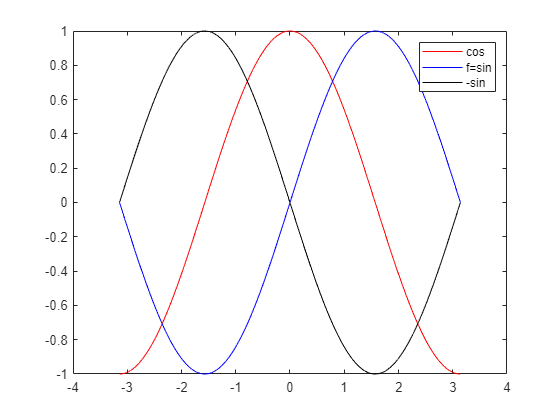

h = 0.001;       % step size
X = -pi:h:pi;    % domain
f = sin(X);      % range
Y = diff(f)/h;   % first derivative
Z = diff(Y)/h;   % second derivative
plot(X(:,1:length(Y)),Y,'r',X,f,'b', X(:,1:length(Z)),Z,'k'),legend('cos','f=sin','-sin')

In this plot the blue line corresponds to the original function, `sin`. The red line corresponds to the calculated first derivative, `cos`, and the black line corresponds to the calculated second derivative, `-sin`.

*Copyright 2015 The MathWorks, Inc.*

### MATLAB®  - Vector gradient

Calculate the 2-D gradient of $x e^{-x^2-y^2}$ on a grid.

x = -2:0.2:2;
y = x';
z = x .* exp(-x.^2 - y.^2);
[px,py] = gradient(z);

Plot the contour lines and vectors in the same figure.

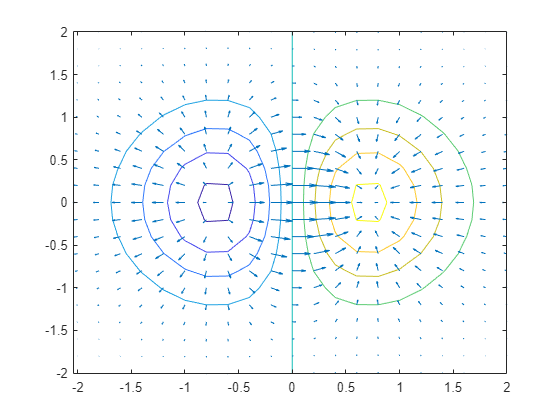

figure
contour(x,y,z)
hold on
quiver(x,y,px,py)
hold off

*Copyright 2012 The MathWorks, Inc.*

## 2. Aprenem... Fòrmules bàsiques.

### Exercici 1. 

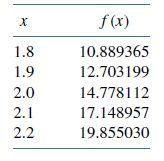

Calcular f'(2.0) con h=0.1 y h=0.2. Los datos son de f(x)=x*e^x, calcular los errores absolutos. Crear tabla para visualitzar error absoluto en las fórmulas usadas

clearvars
x=[1.8:0.1:2.2]; y=[x.*exp(x)]; 
disp([x;y]')

    1.8000   10.8894
    1.9000   12.7032
    2.0000   14.7781
    2.1000   17.1490
    2.2000   19.8550



% valor exacte
valor = exp(2)*3

valor = 22.1672

Fórmula endavant

% formula endavant h=0.2
fp_f02 = (y(5)-y(3))/0.2

fp_f02 = 25.3846

% formula endavant h=0.1
fp_f01 = (y(4)-y(3))/0.1

fp_f01 = 23.7084

% taula resultats
disp(array2table([0.2, fp_f02, abs(fp_f02-valor); 0.1, fp_f01, abs(fp_f01-valor)], 'VariableNames', {'h', 'fprime', 'error_absolut'}))

     h     fprime    error_absolut
    ___    ______    _____________

    0.2    25.385       3.2174    
    0.1    23.708       1.5413    



ratio = abs(fp_f02 - valor)/abs(fp_f01 - valor)

ratio = 2.0875

Fórmula enrere

% formula enrere h=0.2
fp_b02 = (y(3)-y(1))/0.2

fp_b02 = 19.4437

% formula enrere h=0.1
fp_b01 = (y(3)-y(2))/0.1

fp_b01 = 20.7491

% taula resultats
disp(array2table([0.2, fp_b02, abs(fp_b02-valor); 0.1, fp_b01, abs(fp_b01-valor)], 'VariableNames', {'h', 'fprime', 'error_absolut'}))

     h     fprime    error_absolut
    ___    ______    _____________

    0.2    19.444       2.7234    
    0.1    20.749        1.418    



ratio = abs(fp_b02 - valor)/abs(fp_b01 - valor)

ratio = 1.9206

Fórmula centrada

% formula centrada h=0.2
fp_c02 = (y(5)-y(1))/0.4

fp_c02 = 22.4142

% formula centrada h=0.1
fp_c01 = (y(4)-y(2))/0.2

fp_c01 = 22.2288

% taula resultats
disp(array2table([0.2, fp_c02, abs(fp_c02-valor); 0.1, fp_c01, abs(fp_c01-valor)], 'VariableNames', {'h', 'fprime', 'error_absolut'}))

     h     fprime    error_absolut
    ___    ______    _____________

    0.2    22.414       0.24699   
    0.1    22.229      0.061619   



ratio = abs(fp_c02 - valor)/abs(fp_c01 - valor)

ratio = 4.0084

### Exercici 2 

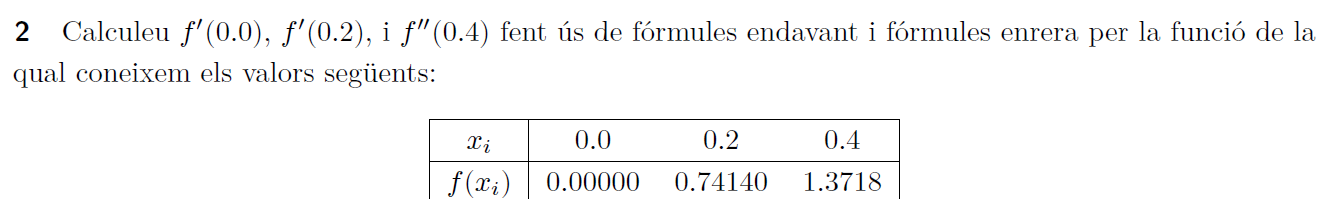

clearvars
x=[0 0.2 0.4]; y=[0 0.74140 1.3718]; 
disp([x;y]')

         0         0
    0.2000    0.7414
    0.4000    1.3718



% formula endavant h=0.2
yp(1:2) = diff(y)./diff(x); yp(3) = NaN %f'(0.0) i f'(0.2)  

yp =     3.7070    3.1520       NaN


% formula enrera h=0.2
yp_b04 = (y(3)-y(2))/0.2, yp_b02 = (y(2)-y(1))/0.2

yp_b04 = 3.1520

yp_b02 = 3.7070

% formula centrada c=0.2
y2p = (y(3)-y(1))/0.4

y2p = 3.4295

### Exercici 3

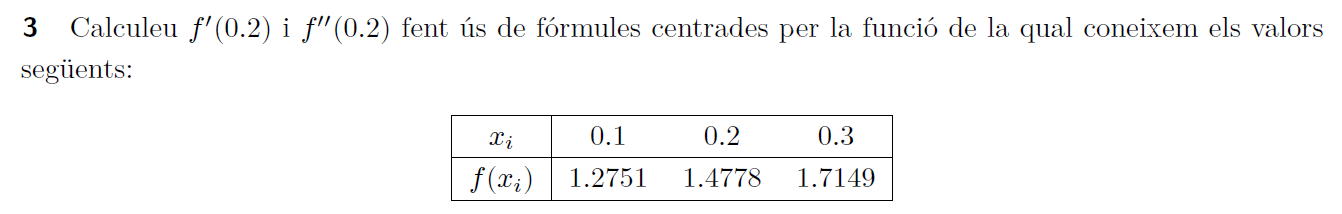

clearvars
x=[0.1, 0.2,0.3]; y=[1.2751 1.4778 1.7149]; 
disp([x;y]')


### **Exercici 4**

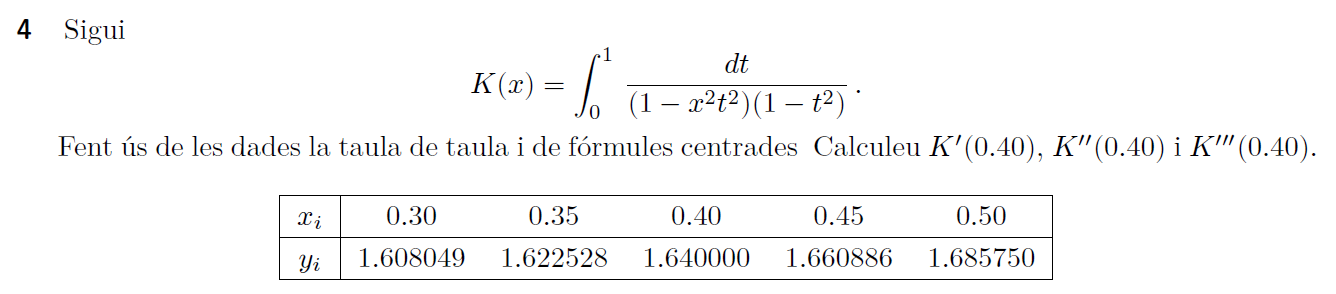

clearvars
x=[0.3:0.05:0.5];
x2=x .^2;
format longG
y = round(ellipke(x2),7,'significant');
T = array2table([x;y]',"VariableNames",{'x_i','y_i'}); disp(T)


## 3. Practiquem...  

### **Exercici 5  **O(h)

Se sabe que la derivada de $\ln(x)$ en $x=2$ tiene el valor de $f^{\prime}(2)=\frac 12$. Se pide:

a) Aproximar $f^{\prime}(2)$ mediante la fórmula $	\mathbf{F1}\::f^{\prime}(x_0)\approx\frac{f(x_0+h)-f(x_0)}{h}
$, per $h_k=5^{-k}$ para $k=1,2,3\dots, 15.$

clearvars
format shortG

k = 1:15;
h = 1./10.^(k);
f1 = (log(2+h)-log(2))./(h);
er = abs(f1-0.5);
ratio = er(1:end-1)./er(2:end); ratio(k(end)) = h(1)/h(2);
disp(table(k',h',f1',er', ratio','VariableNames',{'k','h','fprime(2)','error absolut', 'ratio'}))

    k       h       fprime(2)    error absolut      ratio   
    __    ______    _________    _____________    __________

     1       0.1      0.4879        0.012098          9.7109
     2      0.01     0.49875       0.0012458          9.9701
     3     0.001     0.49988      0.00012496           9.997
     4    0.0001     0.49999        1.25e-05          9.9998
     5     1e-05         0.5        1.25e-06          10.005
     6     1e-06         0.5      1.2494e-07          9.5882
     7     1e-07         0.5      1.3031e-08          4.2882
     8     1e-08         0.5      3.0387e-09        0.073452
     9     1e-09         0.5       4.137e-08               1
    10     1e-10         0.5       4.137e-08               1
    11     1e-11         0.5       4.137e-08      0.00093071
    12     1e-12     0.50004       4

b) Calculad el error absolut opara cada una de las aproximaciones obtenidas. Presentar los resultados en una tabla T2.  Representad el error en una gráfica, absicisas $k=1,2,3\dots, 15$ y ordenadas $log_{10}(error)$

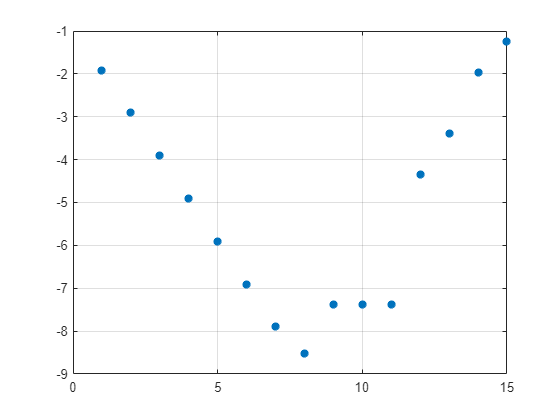

plot(k,log10(er),'*','LineWidth',2),grid

**c) **Observad la existencia de un h óptimo, a partir del cúal si se toman valores de $h$ más pequeños, los errores crecen. Cúal es el valor de h para la fórmula $\mathbf{F1}$?

**RESPUESTA:: **

### **Exercici 6  **O(h^2)

Repetir el ejercicio 5 usando la fórmula $\mathbf{F2}\::f^{\prime}(x_0)\approx\frac{f(x_0+h)-f(x_0-h)}{2h}.$

% Fórmula centrada
clearvars
format shortG
f=@(x)log(x);

k = 1:15;
h = 1./5.^(k);
f1 = (log(2+h)-log(2-h))./(2*h);
er = abs(f1-0.5);
ratio = er(1:end-1)./er(2:end); ratio(k(end)) = (h(1)/h(2))^2;
disp(table(k',h',f1',er', ratio','VariableNames',{'k','h','fprime(2)','error absolut', 'ratio'}))

    k         h         fprime(2)    error absolut     ratio  
    __    __________    _________    _____________    ________

     1           0.2     0.50168       0.0016767        25.145
     2          0.04     0.50007      6.6683e-05        25.006
     3         0.008         0.5      2.6667e-06            25
     4        0.0016         0.5      1.0667e-07            25
     5       0.00032         0.5      4.2667e-09        24.898
     6       6.4e-05         0.5      1.7137e-10        30.043
     7      1.28e-05         0.5      5.7042e-12         1.921
     8      2.56e-06         0.5      2.9694e-12       0.04783
     9      5.12e-07         0.5      6.2083e-11       0.36411
    10     1.024e-07         0.5       1.705e-10      0.085341
    11     2.048e-08         0.5      1.9979e-09             1
    12    

**b)** Calculad el error absoluto para cada una de las aproximaciones obtenidas. Presentar los resultados en una tabla.

Representad el error en una gráfica, abscisas $k=1,2,3\dots, 15$ y ordenadas $log_{10}(error)$

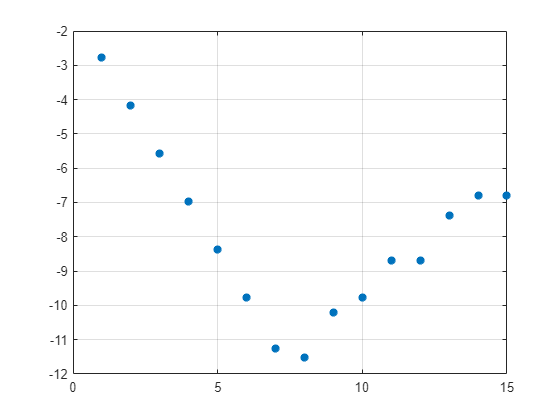

plot(k,log10(er),'*','LineWidth',2),grid

**c) **Observad la existencia de un h óptimo, a partir del cúal si se toman valores de $h$ más pequeños, los errores crecen. 

Cúal es el valor de h para la fórmula $\mathbf{F2}$?

**RESPUESTA:: **

## 4. Practiquem...  

### **Exercici 7  **O(h^2)

Se sabe que la derivada de $\ln(x)$ en $x=2$ tiene el valor de $f^{\prime}(2)=\frac 12$. Se pide:

a) Aproximar $f^{\prime}(2)$ mediante la fórmula $\mathbf{F2}\::f^{\prime}(x_0)\approx\frac{f(x_0+h)-f(x_0-h)}{2h},$ per $h_k=2^{-k}$ para $k=1,2,3\dots, 15.$

clearvars
format shortG
f=@(x)log(x); 
k = 1:6;

h = 1./2.^(k);
f1 = (log(2+h)-log(2-h))./(2*h);
er = abs(f1-0.5);
disp(table(k',h',f1',er','VariableNames',{'k','h','N1','error absolut'}))

    k       h          N1       error absolut
    _    ________    _______    _____________

    1         0.5    0.51083       0.010826  
    2        0.25    0.50263      0.0026289  
    3       0.125    0.50065     0.00065257  
    4      0.0625    0.50016     0.00016286  
    5     0.03125    0.50004     4.0696e-05  
    6    0.015625    0.50001     1.0173e-05  



b) Usad la técnica de Extrapolación de Richardson para obtener $f^{\prime}(2)$ con más decimales correctes. Calculad el error absolut opara cada una de las aproximaciones obtenidas. Presentar los resultados en una tabla T3. Representad el error en una gráfica, absicisas $k=1,2,3\dots, 15$ y ordenadas $log_{10}(error)$.

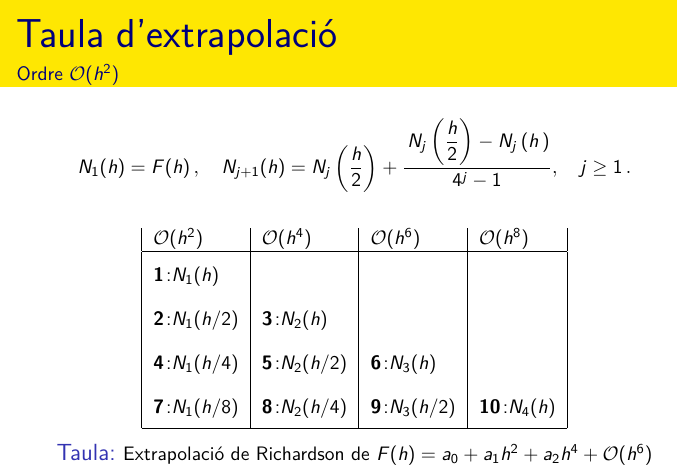

**Primera columna N_1**

N1 = f1

N1 =       0.51083      0.50263      0.50065      0.50016      0.50004      0.50001


m = length(k)

m =      6


**Primera extrapolació, columna N_2**

N2(2:m) =(4*N1(2:m)-N1(1:m-1))/3

N2 =             0       0.4999      0.49999          0.5          0.5          0.5


er = abs(N2'-0.5)

er =           0.5
    0.0001034
   6.1898e-06
    3.828e-07
   2.3863e-08
   1.4904e-09


disp(table(k',h',N1',N2',er,'VariableNames',{'k','h','N1','N2','error absolut'}))

    k       h          N1         N2       error absolut
    _    ________    _______    _______    _____________

    1         0.5    0.51083          0            0.5  
    2        0.25    0.50263     0.4999      0.0001034  
    3       0.125    0.50065    0.49999     6.1898e-06  
    4      0.0625    0.50016        0.5      3.828e-07  
    5     0.03125    0.50004        0.5     2.3863e-08  
    6    0.015625    0.50001        0.5     1.4904e-09  



**Segona extrapolació, columna N_3**

N3(3:m) =(16*N2(3:m)-N2(2:m-1))/15

N3 =             0            0          0.5          0.5          0.5          0.5


er = abs(N3'-0.5); er(1:2) = 0

er =             0
            0
   2.9086e-07
   4.3263e-09
    6.679e-11
   1.0411e-12


disp(table(k',h',N1',N2', N3',er,'VariableNames',{'k','h','N1','N2', 'N3', 'error absolut'}))

    k       h          N1         N2       N3     error absolut
    _    ________    _______    _______    ___    _____________

    1         0.5    0.51083          0      0              0  
    2        0.25    0.50263     0.4999      0              0  
    3       0.125    0.50065    0.49999    0.5     2.9086e-07  
    4      0.0625    0.50016        0.5    0.5     4.3263e-09  
    5     0.03125    0.50004        0.5    0.5      6.679e-11  
    6    0.015625    0.50001        0.5    0.5     1.0411e-12  



**Tercera extrapolació, columna N_4**

N4(4:m) =(64*N3(4:m)-N3(3:m-1))/63

N4 =             0            0            0          0.5          0.5          0.5


er = abs(N4'-0.5); er(1:3) = 0

er =             0
            0
            0
   2.2186e-10
   8.2162e-13
    2.609e-15


disp(table(k',h',N1',N2', N3', N4', er,'VariableNames',{'k','h','N1','N2', 'N3', 'N4', 'error absolut'}))

    k       h          N1         N2       N3     N4     error absolut
    _    ________    _______    _______    ___    ___    _____________

    1         0.5    0.51083          0      0      0              0  
    2        0.25    0.50263     0.4999      0      0              0  
    3       0.125    0.50065    0.49999    0.5      0              0  
    4      0.0625    0.50016        0.5    0.5    0.5     2.2186e-10  
    5     0.03125    0.50004        0.5    0.5    0.5     8.2162e-13  
    6    0.015625    0.50001        0.5    0.5    0.5      2.609e-15  



c) Representad las cifras decimales correctas en una gráfica con $k=1,2,3\dots, 15$ en el eje de abscisas.

## 5. AutoAvaluació 

### Exercici 8

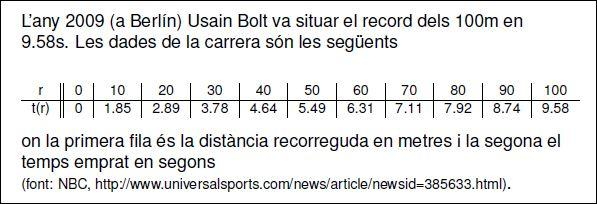

Calculeu una aproximació de la velocitat i l'acceleració en la carrera. Feu una representació gràfica 

dels valors obtinguts

format short g
r=0:10:100;
t=[0 1.85 2.89 3.78 4.64 5.49 6.31 7.11 7.92 8.74 9.58];
disp([r;t]')

**Velocitat i acceleració**

**Gràfics**

### Exercici 9.  O(h)

Se sabe que la derivada de $\ln(x)$ en $x=2$ tiene el valor de $f^{\prime}(2)=\frac 12$. Se pide:

a) Aproximar $f^{\prime}(2)$ mediante la fórmula $	\mathbf{F1}\::f^{\prime}(x_0)\approx\frac{f(x_0+h)-f(x_0)}{h}
$, per $h_k=2^{-k}$ para $k=1,2,3\dots, 15.$

clearvars; 
format short g


b) Usad la técnica de Extrapolación de Richardson para obtener $f^{\prime}(2)$ con más decimales correctes. Calculad el error absoluto  para cada una de las aproximaciones obtenidas. Presentar los resultados en una tabla T. Representad el error en una gráfica, absicisas $k=1,2,3\dots, 15$ y ordenadas $log_{10}(error)$.

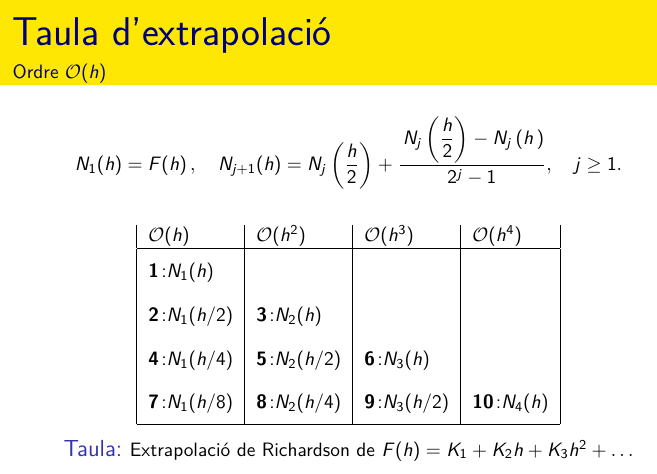

**Primera columna N_1**

**Primera extrapolació, columna N_2**

**Segona extrapolació, columna N_3**

**Tercera extrapolació, columna N_4**

c) Respresentad las cifras decimales correctas en una gráfica con $k=1,2,3\dots, 15$ en el eje de abscisas.

`Document preparat per Mª Àngela Grau Gotés (prof. responsable CN)`